% gpuDeviceCount("available")
% gpuDeviceTable

out

out =   Simulink.SimulationOutput:

                   cost: [1x1 timeseries] 
             laneVector: [1x1 timeseries] 
                  lanes: [1x1 struct] 
                logsout: [1x1 Simulink.SimulationData.Dataset] 
                     mv: [1x1 timeseries] 
             mv_command: [1x1 timeseries] 
                mv_real: [1x1 timeseries] 
                 mv_seq: [1x1 timeseries] 
             solverStat: [1x1 timeseries] 
                  state: [1x1 struct] 
                 status: [1x1 timeseries] 
                      t: [1x1 timeseries] 
                   tout: [101x1 double] 
              waypoints: [1x1 timeseries] 
     waypoints_relative: [1x1 timeseries] 
                  x_seq: [1x1 timeseries] 
                  y_seq: [1x1 timeseries] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


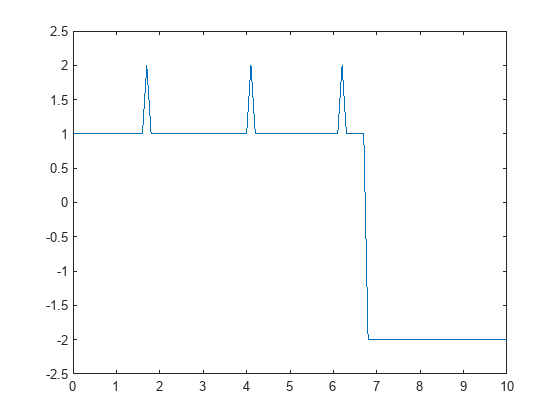


figure
plot(out.solverStat.Time, out.solverStat.Data)
axis([0 10 -2.5 2.5])


i=15;

state_pos=out.state.Position.Data(:,1:2,i);
state_vel=out.state.Velocity.Data(:,1:2,i);
state_ori=out.state.Orientation.Data(:,3,i);

mv_seq=out.mv_seq.Data(:,:,i);
action_i=out.mv.Data(i,:)

action_i =     1.4284    0.0391


state_i=[0,0,0,state_vel(1)]'

state_i =          0
         0
         0
    1.6444



weights=0;
limits=0;
laneCoords=0;
types=0;
nextState_dynamics = vehicleDynamics_Simple(state_i, action_i, ...
    Ts, L, waypoints, weights, limits, ...
    laneCoords, types)

nextState_dynamics =     0.1644
         0
    0.0000
    1.7872



deltaState_pos=out.state.Position.Data(:,1:2,i+1)-out.state.Position.Data(:,1:2,i);
deltaState_ori=out.state.Orientation.Data(:,3,i+1)-out.state.Orientation.Data(:,3,i);
newState_vel=out.state.Velocity.Data(:,1,i+1);
nextState_simulation=[deltaState_pos deltaState_ori newState_vel]'

nextState_simulation =     0.9632
    0.7987
   -0.0017
    1.7233


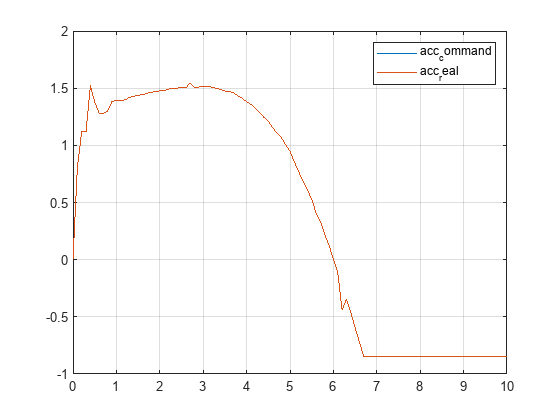

% v=29.3056;
% steer=25;
% 
% beta=atand(tand(steer)/2);
% dyaw=v*cosd(beta)/L*tand(steer);
% yaw_dyn=dyaw*Ts
% 
% beta=atand(tand(rad2deg(steer))/2);
% dyaw=v*cosd(beta)/L*tand(rad2deg(steer));
% yaw_sym=dyaw*Ts


mv_real=out.mv_real.Data;
t_mv_real=out.mv_real.Time;
mv_command=out.mv_command.Data;
t_mv_command=out.mv_command.Time;

figure
plot(t_mv_command,mv_command(:,1))
hold on
plot(t_mv_real,mv_real(:,1))
grid on
legend('acc_command','acc_real')

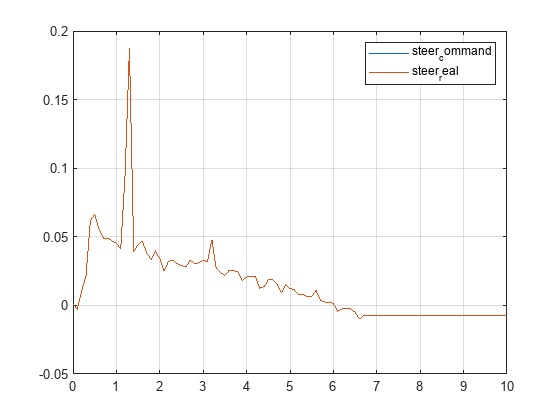


figure
plot(t_mv_command,mv_command(:,2))
hold on
plot(t_mv_real,mv_real(:,2))
grid on
legend('steer_command','steer_real')

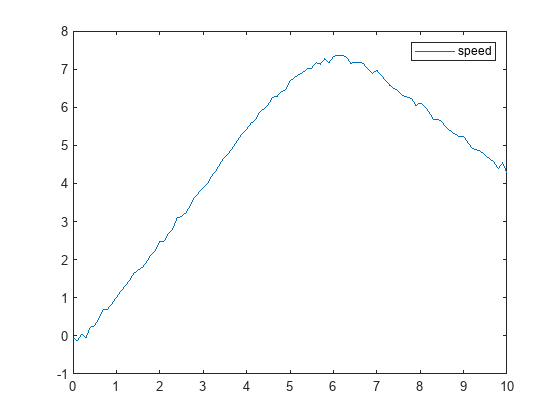

v=out.state.Velocity.Data(1,1,:);
v=reshape(v,[size(v,3),1]);
t_v=out.state.Velocity.Time;
figure
plot(t_v,v)
legend('speed')

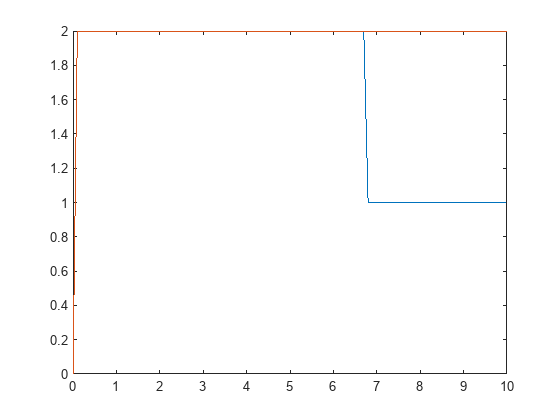


t_lanes=out.lanes.Time.Data;
t_lanes=reshape(t_lanes,1,length(t_lanes));

% numLanes=out.lanes.NumLaneBoundaries.Data;
% numLanes=reshape(numLanes,1,length(numLanes));
% figure
% plot(t_lanes,numLanes)

laneType_l=out.lanes.LaneBoundaries(1).BoundaryType.Data;
laneType_l=reshape(laneType_l,1,length(laneType_l));
laneType_r=out.lanes.LaneBoundaries(2).BoundaryType.Data;
laneType_r=reshape(laneType_r,1,length(laneType_r));
figure
plot(t_lanes,laneType_l)
hold on
plot(t_lanes,laneType_r)


lane=out.lanes.LaneBoundaries(1)

lane = struct with fields:
              Curvature: [1×1 timeseries]
    CurvatureDerivative: [1×1 timeseries]
            CurveLength: [1×1 timeseries]
           HeadingAngle: [1×1 timeseries]
          LateralOffset: [1×1 timeseries]
           BoundaryType: [1×1 timeseries]
               Strength: [1×1 timeseries]
                  Width: [1×1 timeseries]


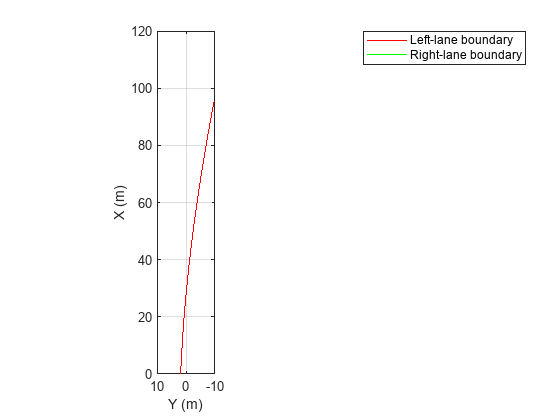

LB_l=clothoidLaneBoundary;
LB_l.Curvature=lane.Curvature.Data(:,:,i);
LB_l.CurvatureDerivative=lane.CurvatureDerivative.Data(:,:,i);
LB_l.CurveLength=lane.CurveLength.Data(:,:,i);
LB_l.HeadingAngle=lane.HeadingAngle.Data(:,:,i);
LB_l.LateralOffset=lane.LateralOffset.Data(:,:,i);
bep = birdsEyePlot('XLimits',[0 120],'YLimits',[-10 10]);
lbPlotter = laneBoundaryPlotter(bep,'DisplayName','Left-lane boundary','Color','r');
rbPlotter = laneBoundaryPlotter(bep,'DisplayName','Right-lane boundary','Color','g');
plotLaneBoundary(lbPlotter,LB_l)
grid
hold on

LB_l_vec=out.laneVector.Data(:,:,i)

LB_l_vec =    -0.1120   -0.1134
    0.0005    0.0005
  100.2997   99.6943
   -2.3954   -2.3830
    1.8679   -2.1290
    2.0000    2.0000


% x_sample=linspace(0,100,101);
% LB_l_y = coumputeBoundary(LB_l_vec(:,1), x_sample);
% plot(x_sample,LB_l_y,'b^')

x_test=[linspace(0,30,10)' ones(10,3)];
u_test=ones(10,2);
weight_test=eye(1);
cost_test = laneKeeping_costFunc(x_test, 1, LB_l_vec, weight_test)

cost_test = 16.6714